# Digital image processing 

Óscar Poblete Sáenz

Course: Introduction to Artificial Intelligence

Teacher: Elizabeth Guevara Martinez

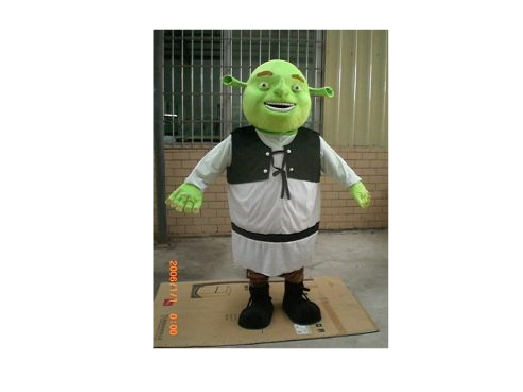

%Tip: go to image view app (from image processing package) >> import from workspace 
% >> Select your image >>Pixel region to see rgb values

clear
clc
close

%Read image
image=imread('Shrek.jpg'); %Upload image to workspace
figure(1)
imshow(image)

size(image) %Three layer

ans =    300   221     3


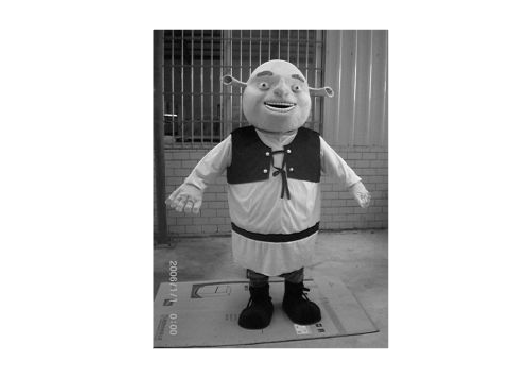

%Convert to greyscale
imageG=rgb2gray(image);

figure(2)
imshow(imageG)

size(imageG) %One layer

ans =    300   221


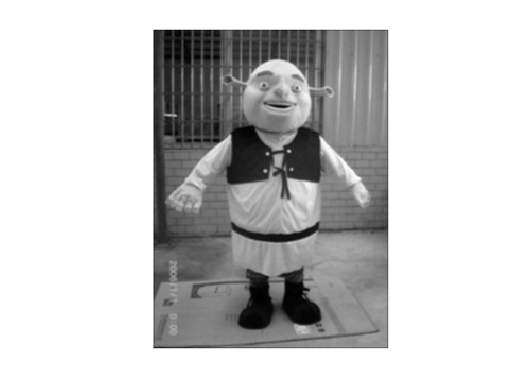

%Set filters
%Lowpass kernel/filter
h= [1 2 1; 2 4 2; 1 2 1]/16; %16 is the sum of the matrix
imagef=imfilter(double(imageG),h);
figure(3)
imshow(imagef,[]) %[] takes all range

%Average filter
h2=fspecial('average',11) %Matrix size: 11x11

h2 =     0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083
    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0083    0.0

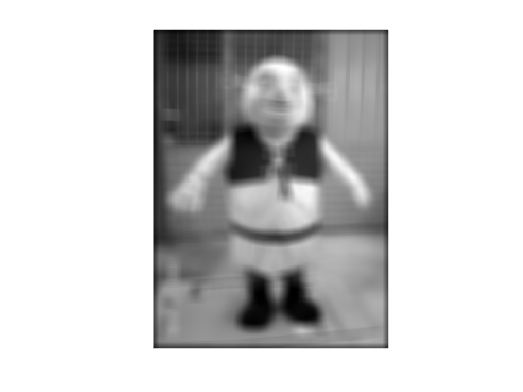

imagef2=imfilter(double(imageG),h2);
figure(4)
imshow(imagef2,[])

%Highpass (Prewit) filter
h3=fspecial('prewitt') %Prewitt size is 3x3

h3 =      1     1     1
     0     0     0
    -1    -1    -1


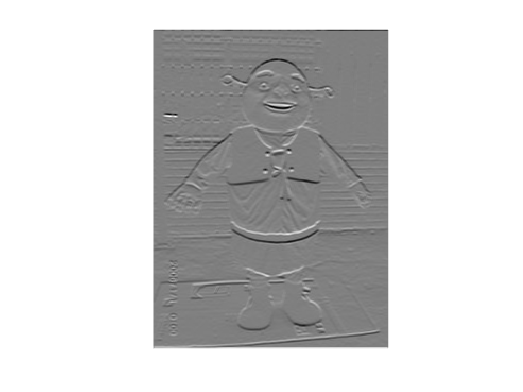

imagef3=imfilter(double(imageG),h3);
figure(5)
imshow(imagef3,[])